# Denavit - Hartenberg Kinematics

clear; clc; close all;
syms t q1t(t) q2t(t) q3t(t) q1 q2 q3 q1p q2p q3p;

## Direct Kinematics & Dynamics

% DH parameters and geometrical properties
nLinks = 4; % considering the base as first link
D=[2 4 0]; A=[1.1 0 1.5]; T=[0 pi/2 -pi/2]; F=[+pi/2 -pi/2 -pi/2];
alpha=pi/6;
P3e=[0;0;0;1];

DHpar=[q1+T(1)  D(1)     A(1)   F(1)-alpha;
       T(2)     q2+D(2)  A(2)   F(2);
       q3+T(3)  D(3)     A(3)   F(3)];

% Define symbolic matrix
[M01,M12,M23,M03(q1,q2,q3)] = DH_total_matrix(DHpar);
M01 = matlabFunction(M01,'Vars',[q1 q2 q3]);
M12 = matlabFunction(M12,'Vars',[q1 q2 q3]);
M23 = matlabFunction(M23,'Vars',[q1 q2 q3]);
% M03 = matlabFunction(M03,'Vars',[q1 q2 q3]);

Mall={M01;M12;M23};

DHdirect = M03*P3e; % Direct kinematics function
DHdirect = matlabFunction(DHdirect,'Vars',[q1 q2 q3]);

% Position of the gripper in the reference system 0 at the initial conditions 
P0e_0=DHdirect(0,0,0)

P0e_0 =     1.1000
   -4.7631
    4.7500
    1.0000


#### Check W and H matrices

DHpar_t=[q1t(t)+T(1)   D(1)          A(1)   F(1)-alpha;
        T(2)          q2t(t)+D(2)   A(2)   F(2);
        q3t(t)+T(3)   D(3)          A(3)   F(3)];
    
[M01_t,M12_t,M23_t] = DH_total_matrix(DHpar_t);

% Link 1
M01p=diff(M01_t,t);
W01_t=M01p*M01_t^-1;
W01=subs(W01_t,[diff(q1t(t),t), diff(q2t(t),t), diff(q3t(t),t), q1t(t), q2t(t), q3t(t)],[q1p q2p q3p q1 q2 q3]);
W01=simplify(W01)

$$W01 = \left(\begin{array}{cccc} 0 & -\mathrm{q1p} & 0 & 0\\ \mathrm{q1p} & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

W01_mlf = matlabFunction(W01,'Vars',[q1p q2p q3p]);

% Link 2
M12p=diff(M12_t,t);
W12_t=M12p*M12_t^-1;
W12=subs(W12_t,[diff(q1t(t),t), diff(q2t(t),t), diff(q3t(t),t), q1t(t), q2t(t), q3t(t)],[q1p q2p q3p q1 q2 q3]);
W12=simplify(W12)

$$W12 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \mathrm{q2p}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

W12_mlf = matlabFunction(W12,'Vars',[q1p q2p q3p]);

% Link 3
M23p=diff(M23_t,t);
W23_t=M23p*M23_t^-1;
W23=subs(W23_t,[diff(q1t(t),t), diff(q2t(t),t), diff(q3t(t),t), q1t(t), q2t(t), q3t(t)],[q1p q2p q3p q1 q2 q3]);
W23=simplify(W23)

$$W23 = \left(\begin{array}{cccc} 0 & -\mathrm{q3p} & 0 & 0\\ \mathrm{q3p} & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

W23_mlf = matlabFunction(W23,'Vars',[q1p q2p q3p]);

### Workspace

Elapsed time is 0.005062 seconds.


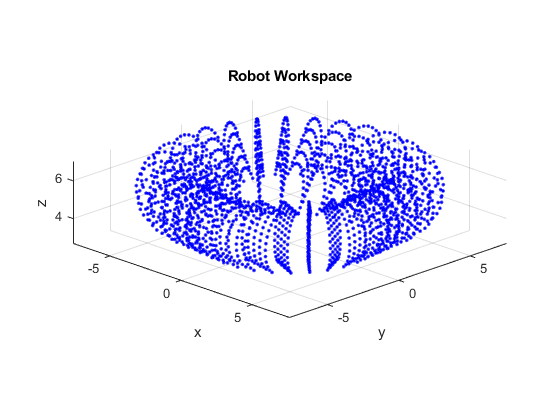

DH_workspace;

### Data of the problem

% TARGET MOTION IN JOINT COORDINATES
target_joints_ini = [-0.3*pi; 1; 0.2*pi];   % Initial position in joint coordinates
target_joints_fin = [0.3*pi; 5; -0.3*pi];   % Final position in joint coordinates
Qini = target_joints_ini;
Qfin = target_joints_fin;

% LAW OF MOTION DATA
Ttot = 5;                 % total time of motion = 5 seconds
nPoints = 100;            % number of points
dT = Ttot/(nPoints-1);    % time step
dq1 = Qfin(1)-Qini(1);    % q1
dq2 = Qfin(2)-Qini(2);    % q2
dq3 = Qfin(3)-Qini(3);    % q3


### Naming convention

Xab_c → matrix of b wrt a in reference frame c

XX_c → array of X matrices in reference frame c

M → position matrix of a reference frame

W → velocity matrix of a reference frame

H → acceleration matrix of a reference frame

Mg → position matrix of a reference frame put in the center of mass of a link

GRIPPER SPACE → x-y-z

JOINT SPACE → q1-q2-q3

### Initialization

kinematics_initialization_matrix;
% dynamics_initialization_matrix;

### Kinematics and dynamics

each_timestep_kin_dyn_matrix;
differential_calculation_matrix;

### Energy and power of the whole body

%{
% TOTAL ENERGY OF THE WHOLE BODY (sum of the energy of each link)
Ek_tot = sum(Ek,1,'omitnan');
Ep_tot = sum(Ep,1,'omitnan');
E_tot = sum(E,1,'omitnan');

% TOTAL POWER OF THE WHOLE BODY (sum of the power of each link) and
% POWER OF JUST WEIGHT FORCES
Wq_tot = sum(Wq,1,'omitnan');
Wext_tot = Wext;
W_tot = sum(W,1,'omitnan');
W_tot_plus_weight = W_tot+sum(Wweight,1,'omitnan');
%}

### Plot results

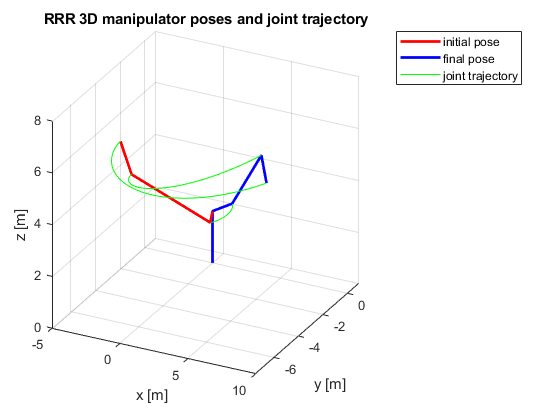

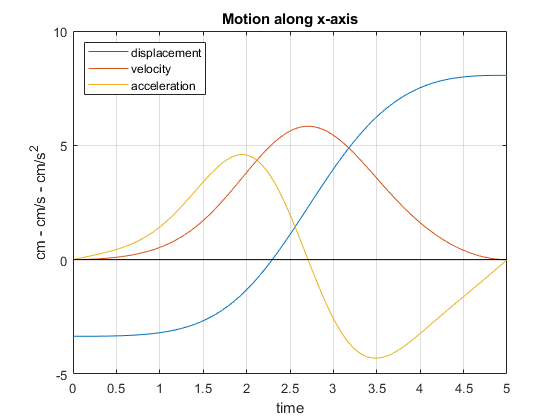

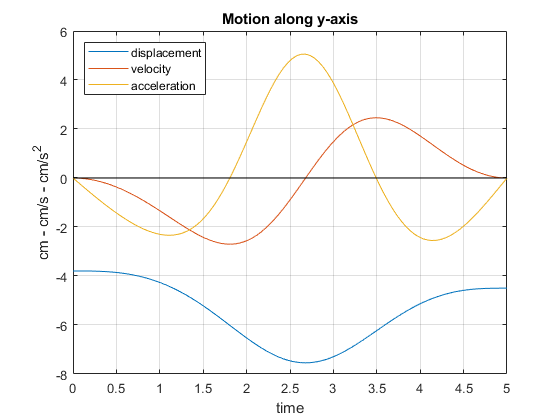

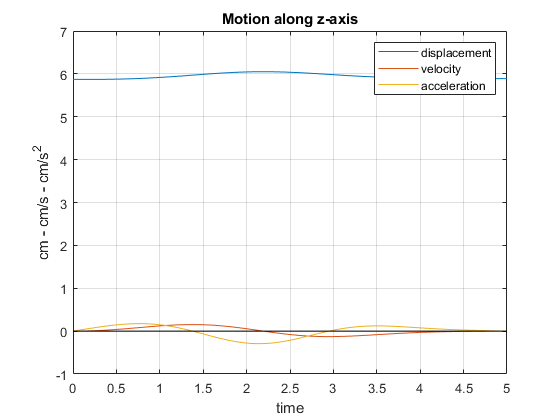

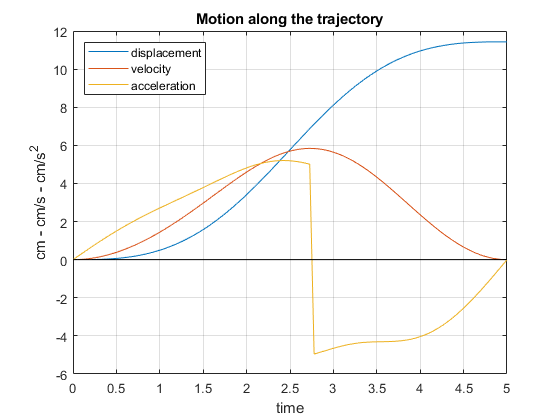

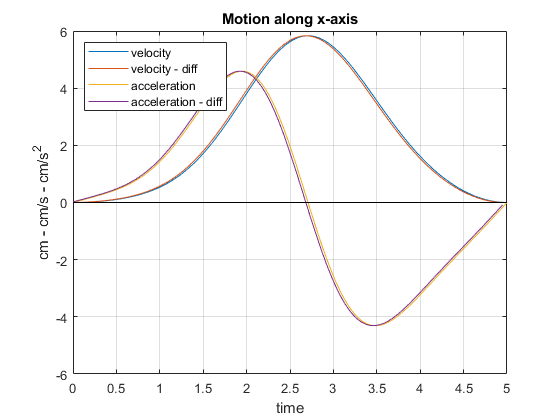

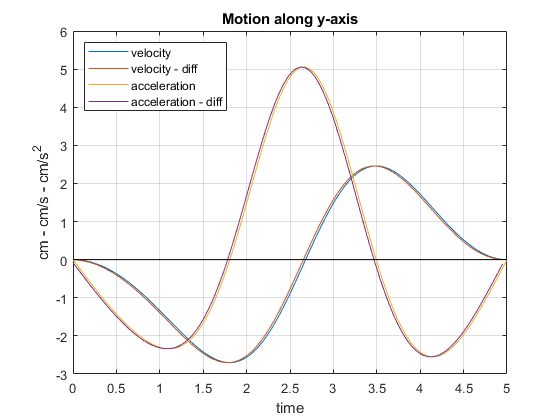

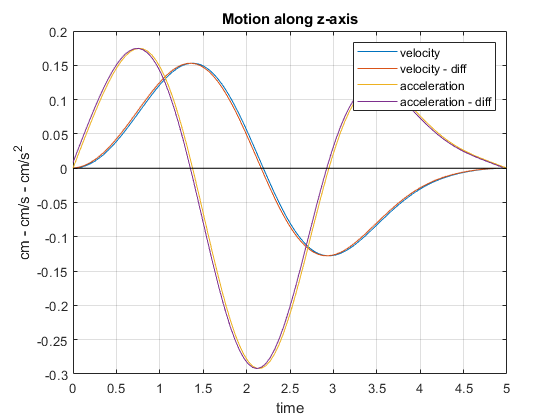

plot_kin_dyn_results_matrix;

## Inverse Kinematics

### Initial position test

figure
plot3(P0e_0(1),P0e_0(2),P0e_0(3),'*r')
hold on

Inverse kinematics:

Q_0 = DHinv(P0e_0,D,A,alpha);
count=0;
for i=1:2   
        P0(i,:)=DHdirect(Q_0(i,1),Q_0(i,2),Q_0(i,3));
    
    if count==0
        plot3(P0(i,1),P0(i,2),P0(i,3),'sg')
    else
        plot3(P0(i,1),P0(i,2),P0(i,3),'.b')
    end

    err(i) = norm(P0(i,:)-P0e_0');
    if err(i)<10^-10
        err(i)=0; 
    end
    count=count+1;
end
err
hold off; grid on;
xlabel('x'); ylabel('y'); zlabel('z')
title('Inv. Kin. Check')
% set(gcf,'Visible','on')

Check robot position

for i=1:size(Q_0,1)
    figure
    DH_plot_robot(Q_0(i,:),D,A,alpha,gcf,P0e_0)
    grid on
    axis equal
    view(90,0)
    xlabel('x'); ylabel('y'); zlabel('z')
    title(['Robot configuration n. ',num2str(i)])
%     set(gcf,'Visible','on')
end

### General position

Dati dei valori di q (Qi), ricavo il corrispondente punto (Pi) con la cinematica diretta.

Qi=[0.5*pi 3 pi/4]
Pi=DHdirect(Qi(1),Qi(2),Qi(3))'

Partendo da un punto Pi, calcolo i valori di q corrispondenti con la cinematica inversa (Qf). Da Qf ricalcolo, poi, Pf con la cinematica diretta. 

Confronto Pf con Pi.

Qf = DHinv(Pi,D,A,alpha)
for i=1:size(Qf,1)
    Pf(i,:)=DHdirect(Qf(i,1),Qf(i,2),Qf(i,3))';
    errP(i)=norm(Pf(i,:)-Pi);
    if errP(i)<10^-10
        errP(i)=0; 
    end 
end
Pf
errP

Confronto le configurazioni del robot per le diverse opzioni date da Qf.

for i=1:size(Qf,1)
    figure
    DH_plot_robot(Qf(i,:),D,A,alpha,gcf,Pi)
    grid on
    axis equal
%     view(90,0)
    xlabel('x'); ylabel('y'); zlabel('z')
    title(['Robot configuration n. ',num2str(i)])
%     set(gcf,'Visible','on')
end